# Dynamic Structural Econometrics - Continuous Choice

## GMM Estimation of Hansen and Singleton (1982) 

**Prepared by Aaron Barkley (University of Melbourne), July 2025**

clear; clc; close all

## Intro

Our first practicum focuses on the estimation of a continuous choice model. We will estimate the model of Hansen and Singleton (1982) that parameterizes a CRRA utility function for a representative consumer model of intertemporal consumption and asset choice. 

## Model

#### Consumption‑based Asset‑Pricing Model

We assume a representative consumer with time‑separable CRRA utility


$$U = \mathbb{E}_0 \Bigl[\,\sum_{t=0}^{\infty} \beta^{t}\,u(C_t)\Bigr],\qquad0<\beta<1,\$$


Later, we will parameterize the utility function as $u(C_t) =  \frac{C_{t}^{\,1-\gamma}}{1-\gamma}$ for $\gamma >0$, but we will leave it in the general form for now.

The consumer also faces a budget constraint:


$$C_t + P_tQ_t \leq (P_t + D_t)Q_{t-1} + W_t$$


where 

- $P_t$ is the price of the asset in time $t$, 

- $Q_t$ is the quantity of the asset held by the consumer, 

- $D_t$ is the dividend paid by the asset, and 

- $W_t$ is the wage income of the consumer. 

The consumer's problem is to maximize their lifetime expected utility subject to the budget constraint. 


$$\max_{C_t,Q_t} \ \mathbb{E}_0 \left[ \sum_{t=0}^{\infty} \beta^{t}u(C_t)\right], \quad \mbox{subject to } C_t + P_tQ_t \leq (P_t + D_t)Q_{t-1} + W_t$$


There are a few ways to solve the consumer's problem, but the simplest is to take the Lagrangian. (There are some additional requirements we need for the Lagrangian approach to be valid in this context, but we'll skip over these). The Lagrangian $\mathcal{L}$ is


$$\mathcal{L} = \mathbb{E}_0 \left[ \sum_{t=0}^{\infty} \beta^{t}u(C_t)\right] - \mathbb{E}_0 \left[ \sum_{t=0}^{\infty} \lambda_t(C_t + P_tQ_t - (P_t + D_t)Q_{t-1} - W_t) \right]$$


Taking the derivative with respect to $C_{\tau}$ and $Q_{\tau}$ gives the following first-order conditions.


$$\frac{\partial \mathcal{L}}{\partial C_{\tau}} = \mathbb{E}_0\left[\beta^{\tau}u'(C_{\tau})\right] - \lambda_{\tau} = 0$$



$$\frac{\partial \mathcal{L}}{\partial Q_{\tau}} = -\lambda_{\tau}P_{\tau} + \lambda_{\tau+1}(P_{\tau+1} + D_{\tau+1}) = 0$$


Combining the two equations to eliminate the $\lambda$ terms allows us to derive the **Euler equation:**


$$\mathbb{E}_t\!\Bigl[\beta \frac{u'(C_{t+1)}}{u'(C_t)}\;R_{t} \;-\; 1\Bigr]\;=\;0 .$$


where $R_t \equiv (P_{t+1} + D_{t+1})/P_t$ is the real gross return on the asset in period $t$.This equation is the starting point for estimating the model.

#### Economic interpretation of the Euler equation

Solutions to economic models involving maximization of consumer utility subject to a budget constraint often take the form of a marginal rate of substitution (MRS) equal to a price ratio, and the Euler equation above has a similar intuition. The term $\frac{u'(C_{t+1)}}{u'(C_t)}$ is the (intertemporal) marginal rate of substition from period $t$ to period $t+1$, and the return on the asset for period $t$ is $R_t = \frac{P_{t+1} + D_{t+1}}{P_t}$, giving rise to a familiar interpretation of the Euler equation we use in estimation.

### Estimation

The equations used in estimation are moment conditions formed from the Euler equations and a set of instruments, which are any variables known by the agent at time $t$. The agent conditions on all known information at time $t$ and, therefore, multiplication by these variables within the expectation term of the Euler equation preserves the equality, as these variables are known constants from the perspective of the agent making the period $t$ decision. 

Define the period $t$ moment condition $m_t$ as 


$$m_t \equiv \mathbb{E}_t\!\Bigl[\beta \frac{u'(C_{t+1)}}{u'(C_t)}\;R_{t} \;-\; 1\Bigr] = 0$$


Then, for a set of instruments $Z_t$ that is included in the information set known to the agent at time $t$ (i.e., $Z_t \in \mathcal{I}_t$), we have moment conditions defined by

$\mathbb{E}_t\!\Bigl[Z_t \left(\beta \frac{u'(C_{t+1})}{u'(C_t)}\;R_{t} \;-\; 1 \right)\Bigr]\;=\;0$.

In practice we will include variables like a constant term, lagged returns, or lagged consumption in the set of instruments.

**Utility parameterization: **Now are now explicit about the parameters we will be estimating:

- the discount factor $\beta$, and 

- the risk aversion parameter $\gamma$, which defines the utility function $u(C_t) =  \frac{C_{t}^{\,1-\gamma}}{1-\gamma}$

The estimation approach seeks to find the utility parameters that minimize the deviation of the moment conditions from zero. 

Defining $g_t(\theta) = Z_t \left(\beta \left(\frac{C_{t+1}}{C_t}\right)^{-\gamma}\;R_{t} \;-\; 1 \right)$, the theoretical model tells us that


$$\mathbb{E}_t[g_t(\theta)] = 0 \qquad \forall t$$


The estimation procedure calculates *sample moments* by taking the sample average of $g_t$ across all observations $t=1,...,T$ and chooses a parameter vector $\theta$ to minimize the deviation of these sample moments from zero to as closely align the theoretical model with the data as possible. We go through the full procedure step-by-step in the coding blocks below.

**Data requirements: **We need data on consumption $C_t$ and asset returns $R_t$ to estimate the model. We obtain these from macroeconomic time series data.

### Empirical implementation

To implement the model, we use four data sets:

- Consumption data (FRED): real personal consumption expenditures (series name PCECC96)

- CPI (FRED): consumer price index to convert nominal returns to real returns (series name CPIAUCSL)

- Value-weighted equity returns (WRDS): value-weighted total market index returns with dividends (CRSP series name: VWRETD)

- Equal-weighted equity returns (WRDS): equally-weighted total market index returns with dividends (CRSP series name: EWRETD)

*Note on sample consutrction:* I load the data from local files below. Without the WRDS/CRSP data, you will need to use different assets in the moment conditions. The $\texttt{readLocal}$ variable toggles whether the WRDS/CSRP data is used from a local file stored in a "Data" subfolder or if all data is downloaded from FRED. If $\texttt{readLocal} == \texttt{false}$, then the implementation uses the following:

- NASDAQ price-only returns for equities (this is the $\texttt{Rv}$ variable defined below, which would otherwise be value-weighted returns).

- Risk-free returns as the second asset (this is the $\texttt{Re}$ variable, which would otherwise be equal-weighted returns).

If you **do not have any data downloaded, **then change $\texttt{readLocal}$ to $\texttt{false}$ in the code block below before running the code.

Much of the coding work is arranging the data. The raw data sets are a mix of daily, monthly, and quarterly observations and report variables in levels or as net returns. For the estimation of the mode we want:

- Quarterly data

- Real gross returns

- Per-capita consumption growth

Below is the code that wrangles the data into the format we require.

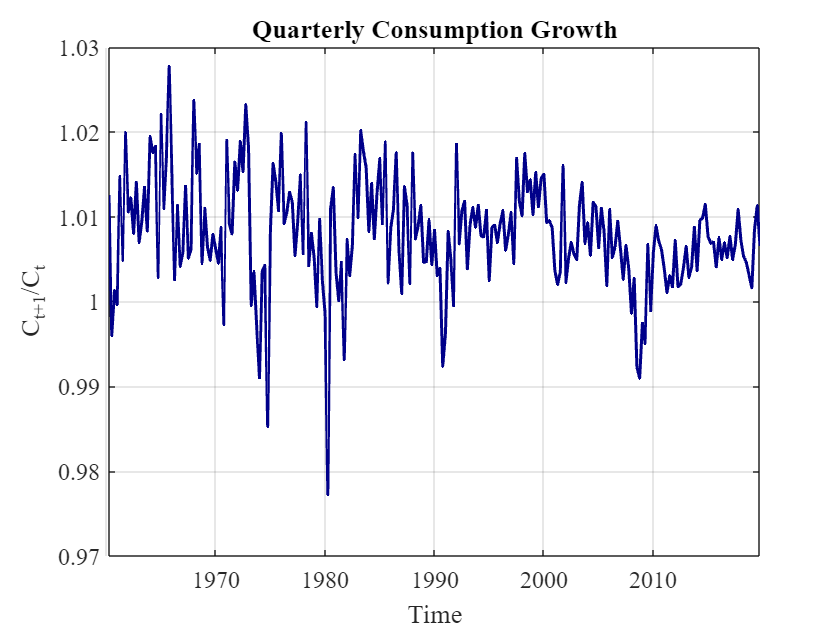

% Change folder paths if your CSVs live elsewhere
datapath = 'Data\';

csvfile  = @(fname) fullfile(datapath,fname);

% Sample end date (start date depends on data used, see below)
endDate   = datetime(2019,12,31);

% Newey‑West bandwidth (quarters)
NWlag = 4;

%% Read raw CSVs

readLocal = true;

if readLocal == true
    startDate = datetime(1960,1,1); % WRDS data goes back to 1960

    pce      = readtable(csvfile('PCECC96.csv'));
    bill_raw = readtable(csvfile('DTB3.csv'));
    cpi_raw  = readtable(csvfile('CPIAUCSL.csv'));
    vwr_raw  = readtable(csvfile('crsp_agg_monthly_total_returns.csv'));
    ewr_raw  = vwr_raw;                   % same file, other column


    vwr_raw = vwr_raw(:,{'DATE','vwretd'});
    vwr_raw.Properties.VariableNames     = {'observation_date','value'};
    ewr_raw = ewr_raw(:,{'DATE','ewretd'});
    ewr_raw.Properties.VariableNames     = {'observation_date','value'};
else
    % Read from the web directly
    startDate = datetime(1972,1,1); % FRED NASDAQ data goes back to 1971

    fredURL = @(series) sprintf(...
        'https://fred.stlouisfed.org/graph/fredgraph.csv?id=%s',series);

    url = fredURL('PCECC96');
    tmp = [tempname,'.csv'];
    websave(tmp, url);
    pce = readtable(tmp);

    url = fredURL('CPIAUCSL');
    tmp = [tempname,'.csv'];
    websave(tmp, url);
    cpi_raw = readtable(tmp);

    url = fredURL('DTB3');
    tmp = [tempname,'.csv'];
    websave(tmp, url);
    bill_raw = readtable(tmp);

    url = fredURL('NASDAQCOM');
    tmp = [tempname,'.csv'];
    websave(tmp, url);
    vwr_raw = readtable(tmp);
    vwr_raw.Properties.VariableNames(2)  = {'value'};
    vwr_raw.value = fillmissing(vwr_raw.value,'linear'); % fill missing values

end


%%% rename columns to generic names
pce.Properties.VariableNames(2)      = {'value'};
bill_raw.Properties.VariableNames(2) = {'value'};
cpi_raw.Properties.VariableNames(2)  = {'value'};

% fill missing values by linear interpolation
bill_raw.value = fillmissing(bill_raw.value,'linear');


%% Aggregate to quarterly 
aggQ = @(tbl,fun) retime(table2timetable(tbl,'RowTimes','observation_date'), ...
                         'quarterly', fun, 'IncludedEdge','right');

pceQ   = table2timetable(pce, 'RowTimes','observation_date');          
billQ  = aggQ(bill_raw, @mean);
cpiQ   = aggQ(cpi_raw,  @mean);
vwrQ   = aggQ(vwr_raw,  @(x) x(end));  % use end-of-period values 
%vwrQ   = aggQ(vwr_raw,  @mean);  % average within period

if readLocal == true
    ewrQ   = aggQ(ewr_raw,  @(x) x(end)); % use end-of-period values
    %ewrQ   = aggQ(ewr_raw,  @mean); % average within-period

    vwrQ = lag(vwrQ,-1); % correct for timing mismatch
    ewrQ = lag(ewrQ,-1);
    
    % Merge & trim sample
    Data = synchronize(pceQ, billQ, cpiQ, vwrQ, ewrQ);
    Data = Data(timerange(startDate,endDate),:);
    Data.Properties.VariableNames = {'pce','disc','cpi','vwr','ewr'};

    % Convert to gross return
    Data.vwr = 1 + Data.vwr;  
    Data.ewr = 1 + Data.ewr;
else
    Data = synchronize(pceQ, billQ, cpiQ, vwrQ);
    Data = Data(timerange(startDate,endDate),:);
    Data.Properties.VariableNames = {'pce','disc','cpi','vwr'};
end 


%% Build variables 
logC   = log(Data.pce);
gLead  = diff(logC);                      % ΔlogC_{t+1}
disc   = Data.disc(1:end-1)/100;          % bill discount at t
Rf_nom = 1 ./ (1 - disc*90/360);          % nominal bill return
pi_t   = Data.cpi(2:end) ./ Data.cpi(1:end-1);
Rf_all = Rf_nom ./ pi_t;                  % real bill return
gLead  = 1 + gLead;                       % C_{t+1}/C_t
n      = length(gLead)-1;
gLag   = gLead(1:n);
gC     = gLead(2:end);                    
Rf     = Rf_all(2:end);
if readLocal == true
    Re_all = Data.ewr(2:end) ./ pi_t;         % real equally‑weighted
    Rv_all = Data.vwr(2:end) ./ pi_t;         % real value‑weighted
else
    Re_all = Rf_all; % Use risk-free rate as second asset    
    Rv_all = (Data.vwr(2:end)./Data.vwr(1:end-1)) ./ pi_t; %use NASDAQ price-only returns as first asset
end
Rv     = Rv_all(2:end);
RvLag  = Rv_all(1:n);
Re     = Re_all(2:end);
ReLag  = Re_all(1:n);

figure(1)
plot(Data.observation_date(2:end), gLead)
xlabel("Time")
ylabel("C_{t+1}/C_t")
title("Quarterly Consumption Growth")

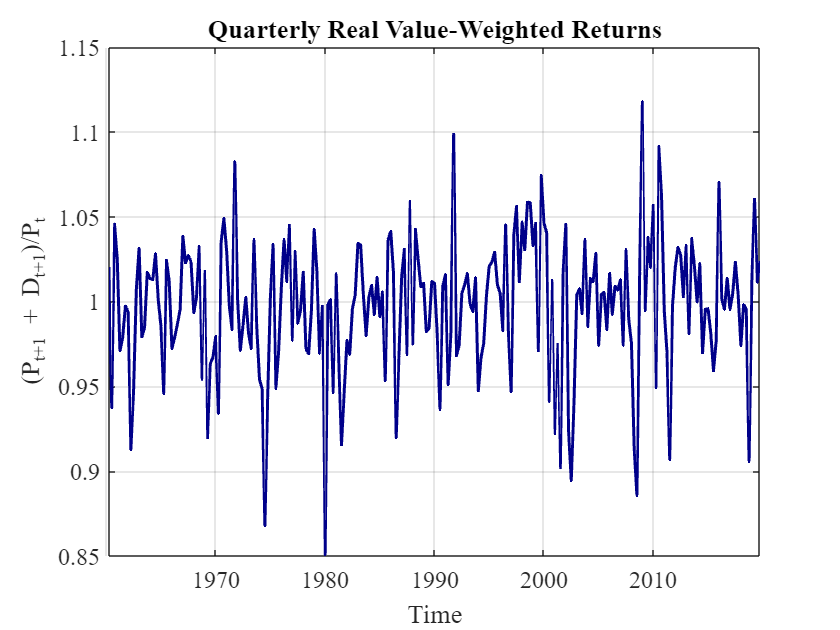

if readLocal==true
    title_str = "Quarterly Real Value-Weighted Returns";
else
    title_str = "Quarterly Price-only NASDAQ Returns";
end
figure(2)
plot(Data.observation_date(2:end), Rv_all)
xlabel("Time")
ylabel("(P_{t+1} + D_{t+1})/P_t")
title(title_str)

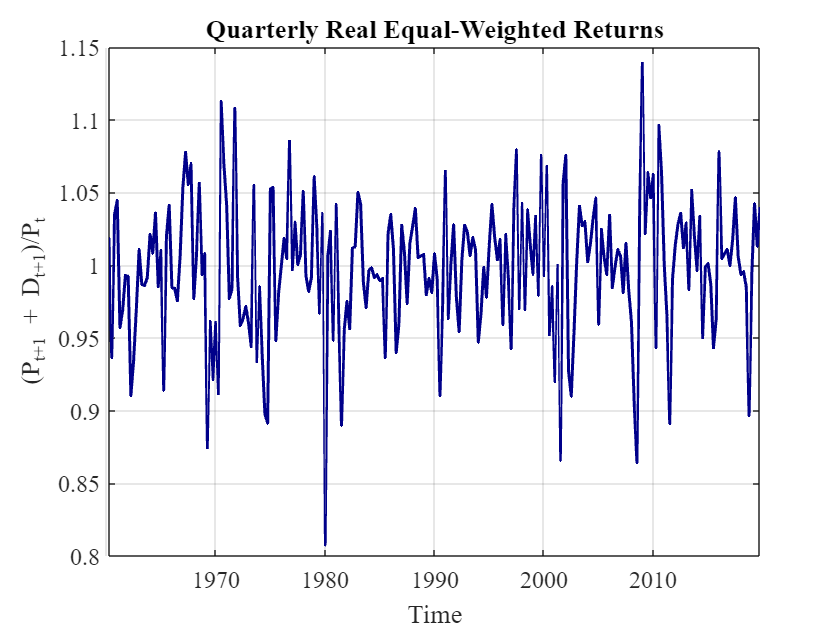


if readLocal==true
    title_str = "Quarterly Real Equal-Weighted Returns";
else
    title_str = "Quarterly Risk-free Returns";
end

figure(3)
plot(Data.observation_date(2:end), Re_all)
xlabel("Time")
ylabel("(P_{t+1} + D_{t+1})/P_t")
title(title_str)

We stack two Euler equations,

$m_{t+1}(\theta)\,R_{e,t} - 1 = 0,\\ m_{t+1}(\theta)\,R_{v,t} - 1 = 0,$,

where $\theta = (\beta,\gamma)$ and $m_{t+1}(\theta)=\beta\,(C_{t+1}/C_t)^{-\gamma}$.

#### GMM Moment Conditions

Choose an instrument vector $Z_t\in\mathcal I_t$ observable at time *t*.

$g_t(\theta) =\left[\begin{array}{c} Z_t\bigl(m_{t+1}(\theta)R_{e,t}-1\bigr)\\ Z_t\bigl(m_{t+1}(\theta)R_{v,t}-1\bigr) \end{array}\right], \qquad \mathbb{E}[g_t(\theta_0)]=0$ .

In our baseline, we will use four instruments (constant, two lagged returns, and lagged consumption) and two asset moments:


$$Z_t=\bigl(1,\;R_{e,t-1},\;R_{v,t-1}, gC_{t-1}\bigr)^{\!\top}, \quad\Longrightarrow\quad \dim(g_t) = 2\times 4 = 8$$


## Two‑step GMM Estimator

**1. Sample moments  **

   $\displaystyle\bar g_T(\theta)=\frac1T\sum_{t=1}^{T} g_t(\theta)$.

Example calculation below, with function definition at the end of the script.

X  = [ones(n,1)  ReLag  RvLag gLag];
L  = size(X,2);
theta0 = [0.99; 5];

ex_m = [theta0(1) * gC.^(-theta0(2)) .* Re - 1 , ...
        theta0(1) * gC.^(-theta0(2)) .* Rv - 1];
ex_g = [X.* ex_m(:,1), X.*ex_m(:,2)];
ex_gbar = mean(ex_g,1)

ex_gbar =    -0.0500   -0.0500   -0.0500   -0.0505   -0.0502   -0.0503   -0.0502   -0.0507


As expected, this is a eight-dimensional vector: four instruments $\times$ two asset prices.

**2. One‑step estimate **

   Minimise $Q_T^{(1)}(\theta)=(\overline{g}_T)^{\top} \times\overline{g}_T $ to obtain $\tilde\theta$.

That is, the first-step estimation solves


$$\min_{\theta} \sum_{k=1}^K \overline{g}_k(\theta)^2$$


where $K$ is the total number of moments. Recall that $K=8$ for our baseline estimation.


g = @(theta) moment_function(theta,gC,Re,Rv,X);
gbar = @(theta) mean(g(theta),1);         % 1×(2L)

Qfun = @(theta,W) gbar(theta) * W * gbar(theta)';

opts = optimoptions('fminunc','Display','iter','Algorithm','quasi-newton');

% --- step 1 (identity) ---
W1   = eye(2*L);
obj1 = @(th) Qfun(th,W1);
theta1 = fminunc(obj1, theta0, opts);

                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           3        0.0201749                         0.772
     1           9       0.00455724            0.1          0.367  
     2          12      1.55295e-07              1       3.45e-06  
     3          15      1.55295e-07              1       3.13e-08  

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


**3. HAC weight matrix  **

   Now we seek to optimally weight each of the moment conditions to obtain a more efficient estimate. First we estimate the long‑run covariance  

    
$$\hat S=\sum_{\ell=-L}^{L}k\!\Bigl(\frac{\ell}{L}\Bigr) \hat\Gamma(\ell), \quad k(u)=1-|u|\ (\text{Bartlett}),\; L=4.$$


See the Newey-West weights function at the end of this script for the code.

**4. Second-step estimate  **

   Now we use the weighting matrix estimated in step 3 to obtain a more efficient estimate for $\theta$. We now minimize

   
$$Q_T(\theta)=\bar g_T^{\top}\,\hat S^{-1}\,\bar g_T$$
  

   starting from $\tilde\theta$.  The result is $\hat\theta=(\hat\beta,\hat\gamma)$, the two-step GMM estimate of $\theta$.

% --- step 2 (NW weight) ---
U1   = g(theta1);
S    = nw_cov(U1, NWlag);
W2   = inv(S);
obj2 = @(th) Qfun(th,W2);
theta = fminunc(obj2, theta1, opts);

                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           3        0.0387604                           1.9
     1          15        0.0363604      0.0013363        0.00523  
     2          33        0.0346551          66430          0.148  
     3          36        0.0342752              1        0.00214  
     4          39        0.0342751              1       2.65e-05  
     5          45        0.0342751       0.315684       1.66e-05  
     6          69        0.0342751     0.00118306       1.05e-05  

Local minimum possible.

fminunc stopped because it cannot decrease the objective function
along the current search direction.

<

**5. Asymptotic variance  and standard errors**

   $\hat V(\hat\theta)= \bigl(D^{\top}\hat S^{-1}D\bigr)^{-1}/T, \quad  D=\frac{\partial\bar g_T(\theta)}{\partial\theta^{\!\top}}\Big|_{\theta=\hat\theta}$.

We use a simple numerical approach (finite differences) for the derivative calculation.

h = 1e-6;
D = zeros(2*L,2);
for j=1:2
    ej = zeros(2,1); ej(j)=h;
    D(:,j) = (gbar(theta+ej) - gbar(theta-ej))'/(2*h);
end
Vtheta = inv(D' * W2 * D) / n;
se     = sqrt(diag(Vtheta));


**6. J‑test for over‑identifying restrictions  **

   
$$J_T = T\,\bar g_T^{\top}\hat S^{-1}\bar g_T \; \overset{d}{\rightarrow}\; \chi^2_{\,6-2=4}.$$



J = n * Qfun(theta, W2);
pJ= 1 - chi2cdf(J, 2*L-2);


**7. Display output**

Output is displayed below. We show the point estimates and standard errors for $\beta$ and $\gamma$ and the test of the overidentifying restrictions. Note that Hansen and Singleton use $\alpha \equiv -\gamma$.

%% Display output
fprintf('\n========= Two‑asset GMM (quarterly) =========\n');


========= Two‑asset GMM (quarterly) =========


fprintf('beta  = %.4f   (se = %.4f)\n', theta(1), se(1));

beta  = 1.0381   (se = 0.0102)


fprintf('gamma = %.4f   (se = %.4f)   [alpha = %.4f]\n',...
        theta(2), se(2), -theta(2));

gamma = 4.1998   (se = 1.1409)   [alpha = -4.1998]


fprintf('J‑stat = %.2f   (df = %d)   p‑val = %.3f\n',...
        J, 2*L-2, pJ);

J‑stat = 8.16   (df = 6)   p‑val = 0.227


## Functions

#### Newey-West weights

function S = nw_cov(U,lag)
    [T,k] = size(U);
    S = (U'*U)/T;
    for j=1:lag
        w = 1 - j/(lag+1);
        Gamma = (U((j+1):end,:)'*U(1:end-j,:))/T;
        S = S + w*(Gamma + Gamma');
    end
end


#### Moment function


function g = moment_function(theta,gC,Re,Rv, X)
    m=[theta(1) * gC.^(-theta(2)) .* Re - 1 , ...
        theta(1) * gC.^(-theta(2)) .* Rv - 1];
    g = [ X.* m(:,1), X.*m(:,2)];

end